# Generate Matrix of Constraints for Portfolio of Asset Investments

Constrain a portfolio of three assets:

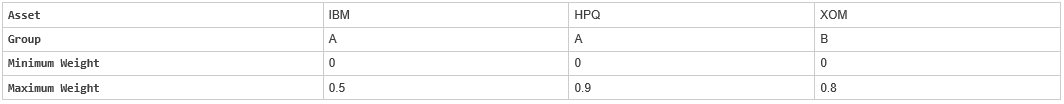

NumAssets = 3;
PVal = 1; % Scale portfolio value to 1.
AssetMin = 0;
AssetMax = [0.5 0.9 0.8];
GroupA = [1 1 0];
GroupB = [0 0 1];
AtoBmax = 1.5 % Value of assets in Group A at most 1.5 times value 
              % in group B.

ConSet = portcons('PortValue', PVal, NumAssets,'AssetLims',... 
AssetMin, AssetMax, NumAssets, 'GroupComparison',GroupA, NaN,... 
AtoBmax, GroupB)

For instance, one possible solution for portfolio weights that satisfy the constraints is 30% in IBM, 30% in HPQ, and 40% in XOM.

*Copyright 2020 The MathWorks, Inc.*